**Problem 0. **Download the .mat file 

file = load('Homework4.mat');

**Problem 1. **The`data1` variable contains 1,000 data points, and the `regressors1` variable contains 100 regressors that might explain these data points. (Note: a constant regressor is already included as the 100th regressor.) Consider a linear model that attempts to predict the data as a weighted sum of the regressors. Apply this model to the data, using bootstrapping (500 iterations) to obtain 95% confidence intervals on the parameters of the model. Visualize these confidence intervals on a figure.

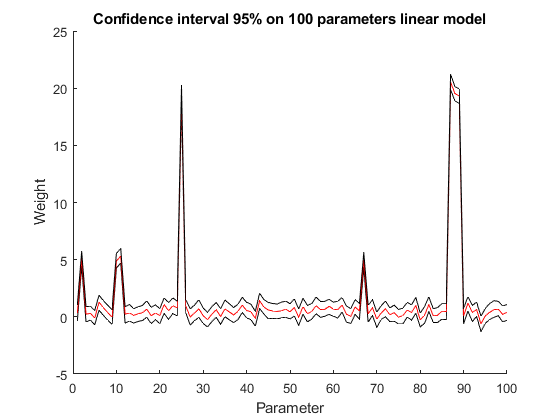

% Bootstrap samples number
numboots = 500;
data = file.data1;
regs = file.regressors1;

% 500 bootstraps, 100 regressors
weights = zeros(500,100);

for i = 1:numboots
    bootidx = ceil(length(data)*rand(1,length(data)));
    X = regs(bootidx,:);
    weights(i,:) = inv(X'*X)*X'*data(bootidx);
end

% Now take the confidence interval of 95%. It means, that from the obtained
% weights only weights between 2.5 and 97.5 percentiles are token. 50
% percentile is for the center line.
confweights = prctile(weights,[2.5 50 97.5], 1);

figure; hold on;
plot(confweights(1,:), 'k-');
plot(confweights(2,:), 'r-');
plot(confweights(3,:), 'k-');
xlabel('Parameter');
ylabel('Weight');
title('Confidence interval 95% on 100 parameters linear model');

hold off;


**Problem 2. **We have 20 subjects and 100 measurements of *x *and *y* from each subject. The `xdata` variable contains the *x*-measurements, and the `ydata `variable contains the *y*-measurements. We want to see whether there is a nonlinear (quadratic) relationship between the *x* variable and the *y *variable. To do this, for each subject, use 10-fold cross-validation to estimate (1) the accuracy of a linear model (*y* = *ax* + *b*) and (2) the accuracy of a quadratic model (*y *=* ax*2 +* bx *+* c*). Use* R*2 to quantify accuracy. Make a scatter plot that compares the accuracy of the linear model and the accuracy of the quadratic model (there should be 20 dots on this scatter plot).

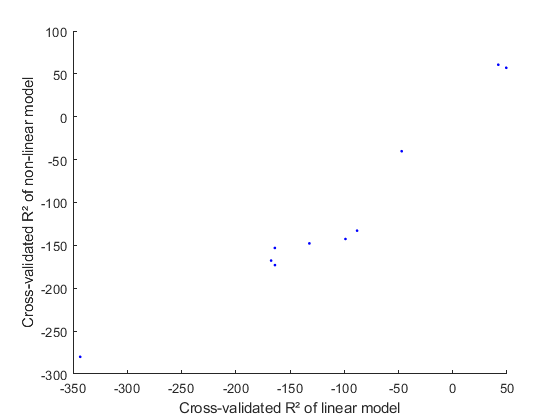

x = file.xdata;
y = file.ydata;

%k-fold validation for k=10
k = 10;
mixed = randperm(length(x));
numingroup = ceil(length(x)/10);
mixed = reshape([mixed NaN(1,k*numingroup-length(x))],k,numingroup);

lpreds = zeros(k, numingroup);
qpreds = zeros(k, numingroup);

for i = 1:k
    testix = mixed(i,:);
    testix(isnan(testix)) = [];
    trainix = setdiff(1:length(x), testix);
    
    % Construct regressors
    Xl = [x(trainix)' ones(length(trainix),1)];
    Xq = [x(trainix)'.^2 x(trainix)' ones(length(trainix),1)];
    % Estimate weights
    wl = inv(Xl'*Xl)*Xl'*y(trainix)';
    wq = inv(Xq'*Xq)*Xq'*y(trainix)';
    % Predict on training data. Regressors are constructed as well
    lpreds(i,:) = [x(testix)' ones(length(testix), 1)] * wl;
    qpreds(i,:) = [x(testix)'.^2 x(testix)' ones(length(testix), 1)] * wq;
end

% Calculate R²s for both models. Since only inputs on testix inputs were
% used, the ouputs at the same indices are chosen.
R2l = 100 * (1-sum((y(testix)-lpreds).^2)/sum((y(testix)-mean(y(testix))).^2));
R2q = 100 * (1-sum((y(testix)-qpreds).^2)/sum((y(testix)-mean(y(testix))).^2));

figure; hold on;
scatter(R2l, R2q, 'b.');
xlabel('Cross-validated R² of linear model');
ylabel('Cross-validated R² of non-linear model');